# Optimización no lineal multidimensional sin restricciones con el método de Cuasi-Newton (BFGS)

**Profesor:** PhD. Marlon E. Moscoso Martínez

% Limpiar la consola, variables y cerrar figuras
clc; clear; close all; 

## Definir la función objetivo 

% Función objetivo f(x1, x2)
f = @(x) (x(1) - 2)^2 + (x(2) - 3)^2 + exp(x(1)^2 + x(2)^2);

% Mostrar la ecuación de la función
disp('Función a Minimizar: f(x_1, x_2) = (x_1 - 2)^2 + (x_2 - 3)^2 + e^{x_1^2 + x_2^2}')

Función a Minimizar: f(x_1, x_2) = (x_1 - 2)^2 + (x_2 - 3)^2 + e^{x_1^2 + x_2^2}


## Paso 1: Definir el punto inicial y opciones del solver

% Punto inicial x0
x0 = [0; 0]; % Iniciamos en el origen [x1, x2]

% Configurar el solver fminunc para usar el método cuasi-Newton (BFGS)
options = optimoptions('fminunc', 'Algorithm', 'quasi-newton', 'Display','iter', 'PlotFcn','optimplotfval');


## Paso 2: Resolver el problema de optimización

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           3               14                             6
     1           6          10.0173       0.166667           4.48  
     2          12          9.50585       0.423128         0.0434  
     3          15          9.50578              1         0.0129  
     4          18          9.50577              1       5.65e-05  
     5          21          9.50577              1       1.19e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

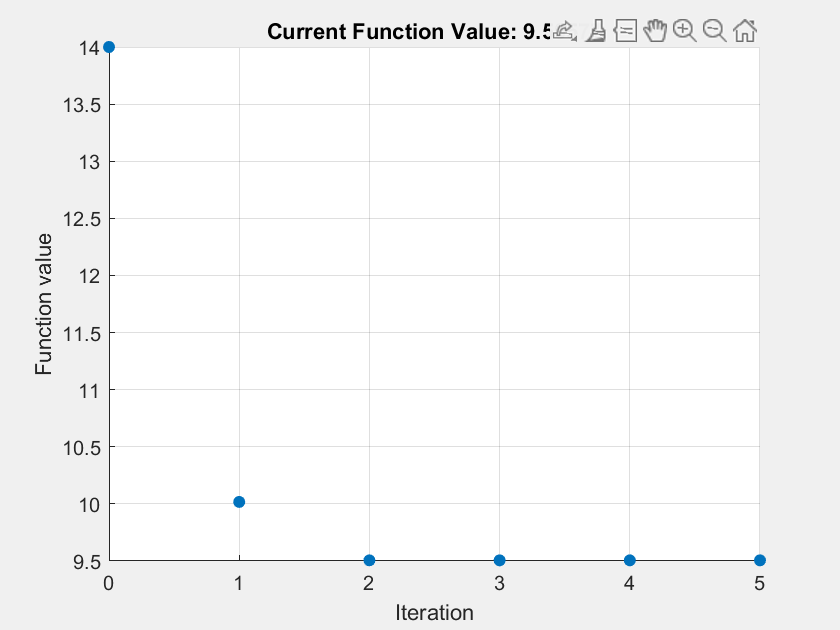

% Ejecutar el solver fminunc para encontrar el mínimo de la función
[x_opt, fval, exitflag, output] = fminunc(f, x0, options);

## Imprimir resultados

% Mostrar resultados
fprintf('Mínimo encontrado en: x1 = %.4f, x2 = %.4f\n', x_opt(1), x_opt(2));

Mínimo encontrado en: x1 = 0.5477, x2 = 0.8216


fprintf('Valor de la función objetivo en el mínimo: %.4f\n', fval);

Valor de la función objetivo en el mínimo: 9.5058


## Visualización gráfica de la función objetivo y la solución

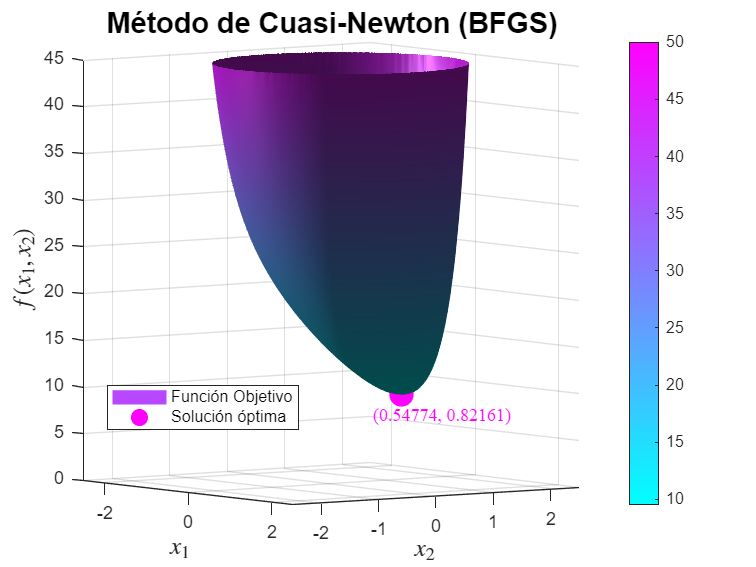

% Gráfico 3D 
[x_vals, y_vals] = meshgrid(-2.5:0.05:2.5, -2.5:0.05:2.5); % Generar malla
f_vals = (x_vals - 2).^2 + (y_vals - 3).^2 + exp(x_vals.^2 + y_vals.^2); % Evaluar f en la malla
% Limitar el valor máximo de f(x_1, x_2) para mejorar visualización
f_vals(f_vals > 50) = 50;
% Graficar la función objetivo
figure;
surf(x_vals, y_vals, f_vals, 'EdgeColor','none'); % Gráfico superficie sin bordes
hold on;

% Añadir detalles
shading interp; % Interpolación de colores para suavizar la superficie
colormap("cool"); 
colorbar; % Mostrar barra de colores
lighting phong; % Mejorar iluminación de la superficie
camlight headlight; % Añadir luz de cámara

% Rotar la vista para apreciar mejor el mínimo
view([414.0 4.1]); % Ajustar ángulo de vista para apreciar el mínimo

% Ajustar los límites de los ejes para mejorar visualización
xlim([-2.5, 2.5]);
ylim([-2.5, 2.5]);
zlim([0, 45]); 

% Marcar la solución óptima en el gráfico
plot3(x_opt(1), x_opt(2), f(x_opt), 'mo', 'MarkerSize', 13, 'MarkerFaceColor','m'); 
text(x_opt(1), x_opt(2) -0.5, f(x_opt)-2, ['(', num2str(x_opt(1)), ', ', num2str(x_opt(2)), ')'],"FontSize",10,"Color",'m','FontName','Times New Roman');

% Etiquetas de los ejes con latex
xlabel('$x_1$', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
ylabel('$x_2$', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
zlabel('$f(x_1, x_2)$', 'Interpreter','latex','FontSize',14,'FontWeight','bold');
% Añadir título descriptivo con latex
title('Método de Cuasi-Newton (BFGS)','FontSize',16,'FontWeight','bold');
legend(["Función Objetivo", "Solución óptima"], "Position", [0.1418 0.2429 0.2536, 0.0774])
grid on;
hold off;